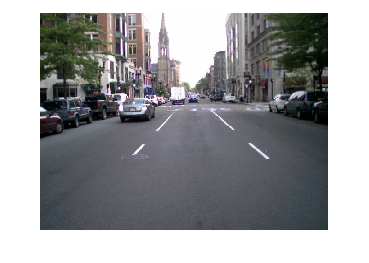

img = imread("street1.jpg");
imshow(img)

classify_noise(img)

ans = logical
   1


function is_noisy = classify_noise(img)
    % Calculate standard deviation of each channel
    std_red = std2(img(:,:,1));
    std_green = std2(img(:,:,2));
    std_blue = std2(img(:,:,3));

    % Define a threshold for noise detection
    noise_threshold = 30;

    % Check if any channel's standard deviation exceeds the threshold
    is_noisy = std_red > noise_threshold || std_green > noise_threshold || std_blue > noise_threshold;
end
